# **LABORATORIO 2 ROBOTICA**

**UNIVERSIDAD NACIONAL DE COLOMBIA**

### **Aristides Daniel Cantero Castillo**

### **Farid Alexis Estepa Quintero **

### **William Andrés Castillo Bautista**

**15 de diciembre del 2021**

PUNTO 1

Para la resolución del problema se descartó la realización del método de desacople cinemático debido que el robot ABB CRB 15000 no posee muñeca esférica, sino con offset, como se aprecia en la imagen:

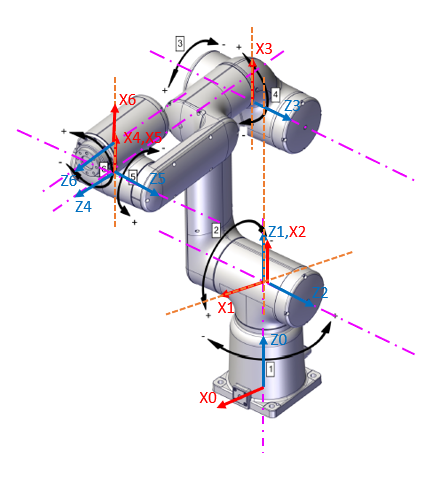

clc
syms theta_1 theta_2 theta_3 theta_4 theta_5 theta_6  
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.037;

%Se crean links, el primer parametro de la funcioón correspode al tipo de articulación. 
% En este caso todas son de tipo rotacional. Después se ingresan los
% parámetros alpha, a, d y offset. Luego se indica que los parametros
% corresponden a MDH. Finalmente se indican los rangos de operación.

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-3.92699 1.48353]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);
% Se articulan todos los links y se le asigna un nombre a todo el sistema
Robot_ABB = SerialLink(L,'name','ABB CRB 15000'); 
%Se plotea el robot, para ciertos ángulos theta.


Para resolver el robot se decidió posteriormente realizar un análisis de la ecuación matricial entre las transformaciones de las articulaciones y la matriz final, con el objetivo de obtener ecuaciones en términos capaces de ser despejados.

### Matrices de transformación homogenea

T_0_1=L(1).A(theta_1)

$$T\_0\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & \frac{53}{200}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_1_2=L(2).A(theta_2);
T_1_2=[cos(theta_2-pi/2) -sin(theta_2-pi/2) 0 0
    0 0 1 0
    -sin(theta_2-pi/2) -cos(theta_2-pi/2) 0 0
    0 0 0 1]

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{2}-\frac{\pi }{2}\right) & -\sin\left(\theta_{2}-\frac{\pi }{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ -\sin\left(\theta_{2}-\frac{\pi }{2}\right) & -\cos\left(\theta_{2}-\frac{\pi }{2}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_2_3=L(3).A(theta_3)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & \frac{111}{250}\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_3_4=L(4).A(theta_4);
T_3_4=[cos(theta_4) -sin(theta_4) 0 11/100
    0 0 1 47/100
    -sin(theta_4) -cos(theta_4) 0 0
    0 0 0 1]

$$T\_3\_4 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right) & 0 & \frac{11}{100}\\ 0 & 0 & 1 & \frac{47}{100}\\ -\sin\left(\theta_{4}\right) & -\cos\left(\theta_{4}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_4_5=L(5).A(theta_5);
T_4_5=[cos(theta_5) -sin(theta_5) 0 0
    0 0 -1 0
    sin(theta_5) cos(theta_5) 0 0
    0 0 0 1]

$$T\_4\_5 = \left(\begin{array}{cccc} \cos\left(\theta_{5}\right) & -\sin\left(\theta_{5}\right) & 0 & 0\\ 0 & 0 & -1 & 0\\ \sin\left(\theta_{5}\right) & \cos\left(\theta_{5}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_5_6=L(6).A(theta_6);
T_5_6=[cos(theta_6) -sin(theta_6) 0 2/25
    0 0 1 37/1000
    -sin(theta_6) -cos(theta_6) 0 0
    0 0 0 1]

$$T\_5\_6 = \left(\begin{array}{cccc} \cos\left(\theta_{6}\right) & -\sin\left(\theta_{6}\right) & 0 & \frac{2}{25}\\ 0 & 0 & 1 & \frac{37}{1000}\\ -\sin\left(\theta_{6}\right) & -\cos\left(\theta_{6}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%T_0_6=T_0_1*T_1_2*T_2_3*T_3_4*T_4_5*T_5_6
%Robot_ABB.plot([0,0,0,0,0,0],'workspace',[-0.5 0.5 -0.5 0.5 -0.1 1],'scale',0.5,'noa', 'view',[140 20])


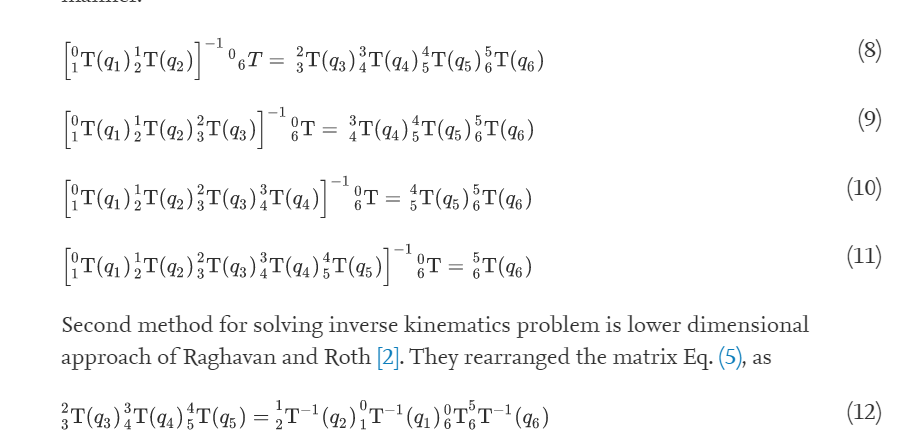

 Las ecuación más viable a despejar es la ecuación 9, en la cual se obtiene la forma: 

syms r11 r12 r13 r21 r22 r23 r31 r32 r33 px py pz
R=[r11 r12 r13 
   r21 r22 r23
   r31 r32 r33];
p=[px;   py;    pz];
T_0_6=[R,p;0 0 0 1];

T_3_4*T_4_5*T_5_6

$$ans = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\cos\left(\theta_{6}\right)-\sin\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right) & -\cos\left(\theta_{6}\right)\,\sin\left(\theta_{4}\right)-\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{6}\right) & -\cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right) & \frac{2\,\cos\left(\theta_{4}\right)\,\cos\left(\theta_{5}\right)}{25}-\frac{37\,\cos\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)}{1000}+\frac{11}{100}\\ \cos\left(\theta_{6}\right)\,\sin\left(\theta_{5}\right) & -\sin\left(\theta_{5}\right)\,\sin\left(\theta_{6}\right) & \cos\left(\theta_{5}\right) & \frac{37\,\cos\left(\theta_{5}\right)}{1000}+\frac{2\,\sin\left(\theta_{5}\right)}{25}+\frac{47}{100}\\ -\cos\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right)-\cos\left(\theta_{5}\right)\,\cos\left(\theta_{6}\right)\,\sin\left(\theta_{4}\right) & \cos\left(\theta_{5}\right)\,\sin\left(\theta_{4}\right)\,\sin\left(\theta_{6}\right)-\cos\left(\theta_{4}\right)\,\cos\left(\theta_{6}\right) & \sin\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right) & \frac{37\,\sin\left(\theta_{4}\right)\,\sin\left(\theta_{5}\right)}{1000}-\frac{2\,\cos\left(\theta_{5}\right)\,\sin\left(\theta_{4}\right)}{25}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

inv(T_2_3)*inv(T_1_2)*inv(T_0_1)*T_0_6

sin embargo, se puede apreciar en todas las columnas y filas de la igualdad matricial ecuaciones trigonométricas de 3 variables, las cuales no están dentro de los recursos y herramientas para el curso y por otro lado son muy extensas y de orden muy alto para resolverlas, inclusive con cambio de variable, por este motivo se descartó completamente la idea.

# Método utilizado

Para resolver el robot es de destacar que la articulación número 4 genera inconventes a la hora de resolver la cinemática inversa, ya que aumenta el orden de las variables que se pueden despejar y geométricamente altera todas las variables de la pose del efector, es por esto que se ha decidido restringir esta variable y aprovechar el método geométrico basado en esta suposición. Con esto en mente, se definde $\theta_4 :=0$.

## Método geométrico para las 3 primeras articulaciones

Al restringir la 4ta articulación, se puede reevaluar el robot geométricamente de la siguiente forma:

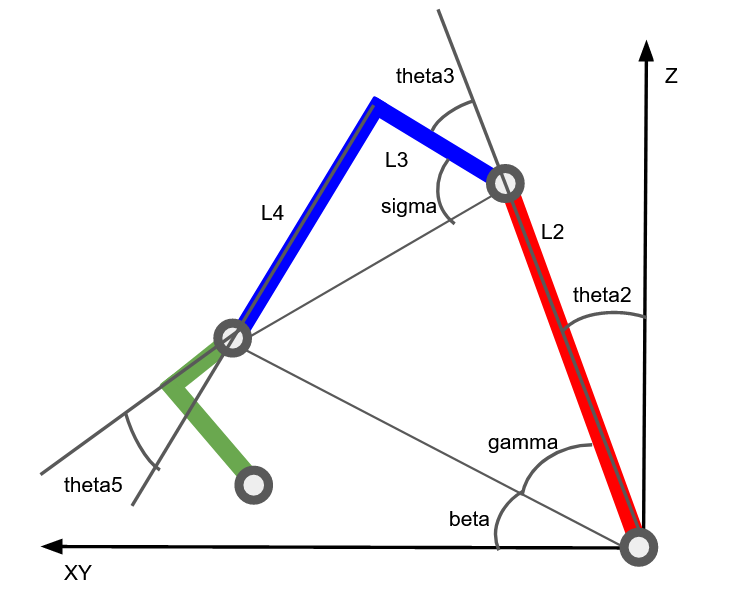

Para la facilidad de los cálculos, se realiza una transformación que mueve la pose del efector final hasta la articulación 5, basados en las traslaciones desde 6 a 5 con ayuda del vector:


$$$$


**Robot ABB CRB 15000**

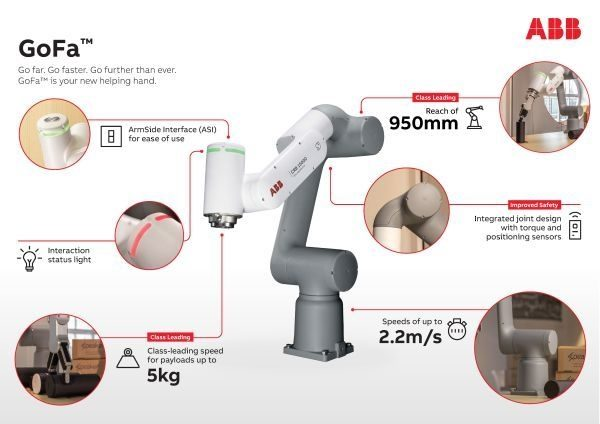

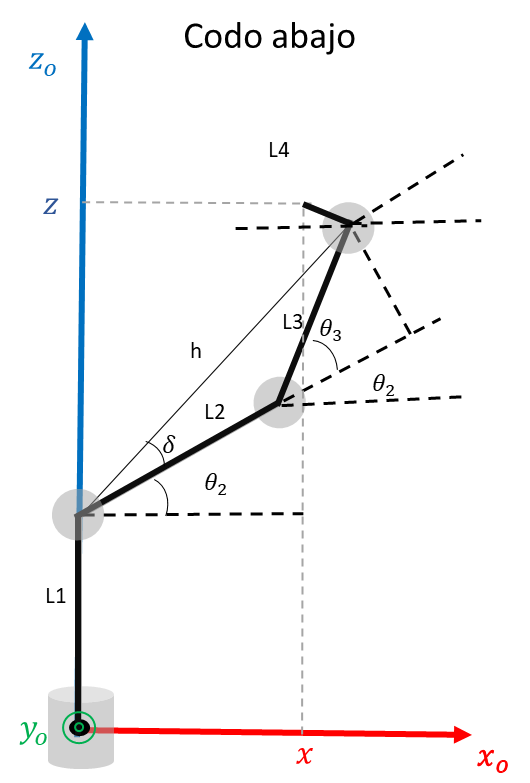


$$\begin{array}{l}
x={\cos \left(\theta_2 \right)L}_2 +L_3 \;\cos \left(\theta_3 +\theta_2 \right)-L_4 \;\cos \left(\frac{\pi }{2}-\left(\theta_3 +\theta_2 \right)\right)\\
z=L_1 +L_2 \;\sin \;\left(\theta_2 \right)+L_3 \sin \left(\theta_3 +\theta_4 \right)+L_4 \;\sin \left(\frac{\pi }{2}-\left(\theta_3 +\theta_4 \right)\right)
\end{array}$$



$$\begin{array}{l}
\\
\\
\\
{r^{\prime } }^2 =x^2 +y^2 -d^2 \\
h^2 =s^2 +{r^{\prime } }^2 \\
h^2 =l_2^2 +l_3^2 -2l_2 l_3 \cos \left({\pi -\;\theta }_3 \right)\\
h^2 =l_2^2 +l_3^2 +2l_2 l_3 \cos \left({\;\theta }_3 \right)\\
\cos \left({\;\theta }_3 \right)=\frac{h^2 -l_2^2 -l_3^2 }{2l_2 l_3 }\\
\textrm{sen}\left(\theta_3 \right)=\sqrt{1-{\cos \left(\theta_3 \right)}^2 }\\
\theta_3 =\arctan \left(\frac{\sqrt{1-{\cos \left(\theta_3 \right)}^2 }}{\frac{h^2 -l_2^2 -l_3^2 }{2l_2 l_3 }}\right)\\
\theta_3 =\arctan \left(\frac{\sqrt{1-{\left(\frac{h^2 -l_2^2 -l_3^2 }{2l_2 l_3 }\right)}^2 }}{\frac{h^2 -l_2^2 -l_3^2 }{2l_2 l_3 }}\right)
\end{array}$$



$$\begin{array}{l}
\theta_2 =\arctan \left(\frac{s}{r^{\prime } }\right)-\delta \\
\delta =\arctan \left(\frac{l_3 \textrm{sen}\left(\theta_3 \right)}{l_2 +l_3 \cos \left(\theta_3 \right)}\right)\\
\theta_2 =\arctan \left(\frac{s}{r^{\prime } }\right)-\arctan \left(\frac{l_3 \textrm{sen}\left(\theta_3 \right)}{l_2 +l_3 \cos \left(\theta_3 \right)}\right)
\end{array}$$


Ahora, codo arriba.

**Tabla de parámetros DH.**

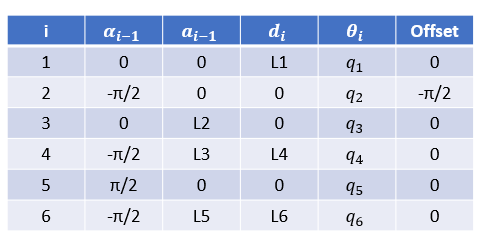

clc
syms theta_1 theta_2 theta_3 theta_4 theta_5 theta_6  
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.037;

%Se crean links, el primer parametro de la funcioón correspode al tipo de articulación. 
% En este caso todas son de tipo rotacional. Después se ingresan los
% parámetros alpha, a, d y offset. Luego se indica que los parametros
% corresponden a MDH. Finalmente se indican los rangos de operación.

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-3.92699 1.48353]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);
% Se articulan todos los links y se le asigna un nombre a todo el sistema
Robot_ABB = SerialLink(L,'name','ABB CRB 15000'); 
%Se plotea el robot, para ciertos ángulos theta.


### Matrices de transformación homogenea

T_0_1=L(1).A(theta_1)

$$T\_0\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & \frac{53}{200}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_1_2=L(2).A(theta_2);
T_1_2=[cos(theta_2-pi/2) -sin(theta_2-pi/2) 0 0
    0 0 1 0
    -sin(theta_2-pi/2) -cos(theta_2-pi/2) 0 0
    0 0 0 1]

$$T\_1\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{2}-\frac{\pi }{2}\right) & -\sin\left(\theta_{2}-\frac{\pi }{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ -\sin\left(\theta_{2}-\frac{\pi }{2}\right) & -\cos\left(\theta_{2}-\frac{\pi }{2}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_2_3=L(3).A(theta_3)

$$T\_2\_3 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & \frac{111}{250}\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_3_4=L(4).A(theta_4);
T_3_4=[cos(theta_4) -sin(theta_4) 0 11/100
    0 0 1 47/100
    -sin(theta_4) -cos(theta_4) 0 0
    0 0 0 1]

$$T\_3\_4 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right) & 0 & \frac{11}{100}\\ 0 & 0 & 1 & \frac{47}{100}\\ -\sin\left(\theta_{4}\right) & -\cos\left(\theta_{4}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_4_5=L(5).A(theta_5);
T_4_5=[cos(theta_5) -sin(theta_5) 0 0
    0 0 -1 0
    sin(theta_5) cos(theta_5) 0 0
    0 0 0 1]

$$T\_4\_5 = \left(\begin{array}{cccc} \cos\left(\theta_{5}\right) & -\sin\left(\theta_{5}\right) & 0 & 0\\ 0 & 0 & -1 & 0\\ \sin\left(\theta_{5}\right) & \cos\left(\theta_{5}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_5_6=L(6).A(theta_6);
T_5_6=[cos(theta_6) -sin(theta_6) 0 2/25
    0 0 1 37/1000
    -sin(theta_6) -cos(theta_6) 0 0
    0 0 0 1]

$$T\_5\_6 = \left(\begin{array}{cccc} \cos\left(\theta_{6}\right) & -\sin\left(\theta_{6}\right) & 0 & \frac{2}{25}\\ 0 & 0 & 1 & \frac{37}{1000}\\ -\sin\left(\theta_{6}\right) & -\cos\left(\theta_{6}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%T_0_6=T_0_1*T_1_2*T_2_3*T_3_4*T_4_5*T_5_6
%Robot_ABB.plot([0,0,0,0,0,0],'workspace',[-0.5 0.5 -0.5 0.5 -0.1 1],'scale',0.5,'noa', 'view',[140 20])


syms r11 r12 r13 r21 r22 r23 r31 r32 r33 px py pz
R=[r11 r12 r13 
   r21 r22 r23
   r31 r32 r33];
p=[px;   py;    pz];
T_0_6=[R,p;0 0 0 1];
subs(T_3_4,theta_4,0)*T_4_5*T_5_6

$$ans = \left(\begin{array}{cccc} \cos\left(\theta_{5}\right)\,\cos\left(\theta_{6}\right) & -\cos\left(\theta_{5}\right)\,\sin\left(\theta_{6}\right) & -\sin\left(\theta_{5}\right) & \frac{2\,\cos\left(\theta_{5}\right)}{25}-\frac{37\,\sin\left(\theta_{5}\right)}{1000}+\frac{11}{100}\\ \cos\left(\theta_{6}\right)\,\sin\left(\theta_{5}\right) & -\sin\left(\theta_{5}\right)\,\sin\left(\theta_{6}\right) & \cos\left(\theta_{5}\right) & \frac{37\,\cos\left(\theta_{5}\right)}{1000}+\frac{2\,\sin\left(\theta_{5}\right)}{25}+\frac{47}{100}\\ -\sin\left(\theta_{6}\right) & -\cos\left(\theta_{6}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

simplify(inv(T_2_3)*inv(T_1_2)*inv(T_0_1)*T_0_6)

### 3. Haga uso de las funciones del RVC para hallar la cinemática inversa de su robot asignado y compruebe los resultados del punto anterior. Ya que existen varias funciones en el *Toolbox *explique:

### ¿Cuál es la diferencia entre estas funciones?

### ¿Cuál debe usar para su robot y por qué? (Revise la documentación del *Toolbox*)  

clc

Robot_ABB = SerialLink(L,'name','ABB CRB 15000'); 

Target = [1 0 0 0.5
          0 1 0 0.5
          0 0 1 0.5
          0 0 0 1];
qSolve = Robot_ABB.ikunc(Target); 	%inverse kinematics using optimisation

q1 = qSolve(1)*(180/pi)

q1 = 45.0000

q2 = qSolve(2)*(180/pi)

q2 = 45.6755

q3 = qSolve(3)*(180/pi)

q3 = -19.0581

q4 = qSolve(4)*(180/pi)

q4 = -3.8479e-06

q5 = qSolve(5)*(180/pi)

q5 = -116.6174

q6 = qSolve(6)*(180/pi)

q6 = 135.0000

Robot_ABB.plot([q1 q2 q3 q4 q5 q6],'workspace',[-0.5 0.5 -0.5 0.5 -0.1 1],'scale',0.5,'noa', 'view',[140 20])

qSolve = Robot_ABB.ikine(Target); 	%inverse kinematics using iterative numerical method

q1 = qSolve(1)*(180/pi)

q1 = 45.0000

q2 = qSolve(2)*(180/pi)

q2 = 45.6755

q3 = qSolve(3)*(180/pi)

q3 = -19.0581

q4 = qSolve(4)*(180/pi)

q4 = -6.6918e-07

q5 = qSolve(5)*(180/pi)

q5 = -116.6174

q6 = qSolve(6)*(180/pi)

q6 = 135.0000

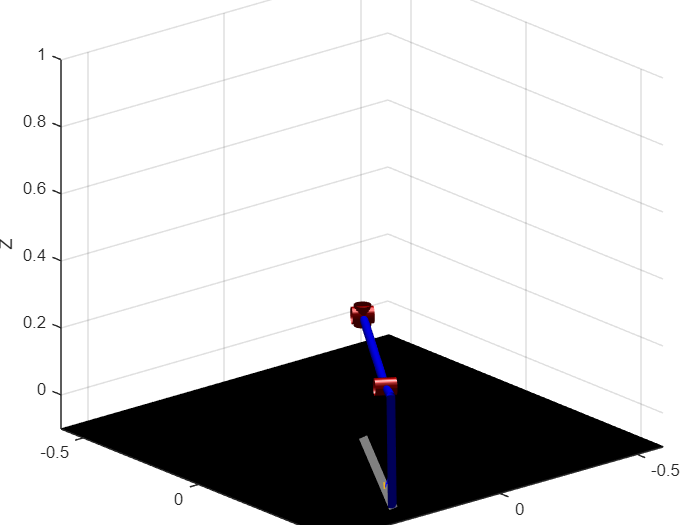

Robot_ABB.plot([q1 q2 q3 q4 q5 q6],'workspace',[-0.5 0.5 -0.5 0.5 -0.1 1],'scale',0.5,'noa', 'view',[140 20])

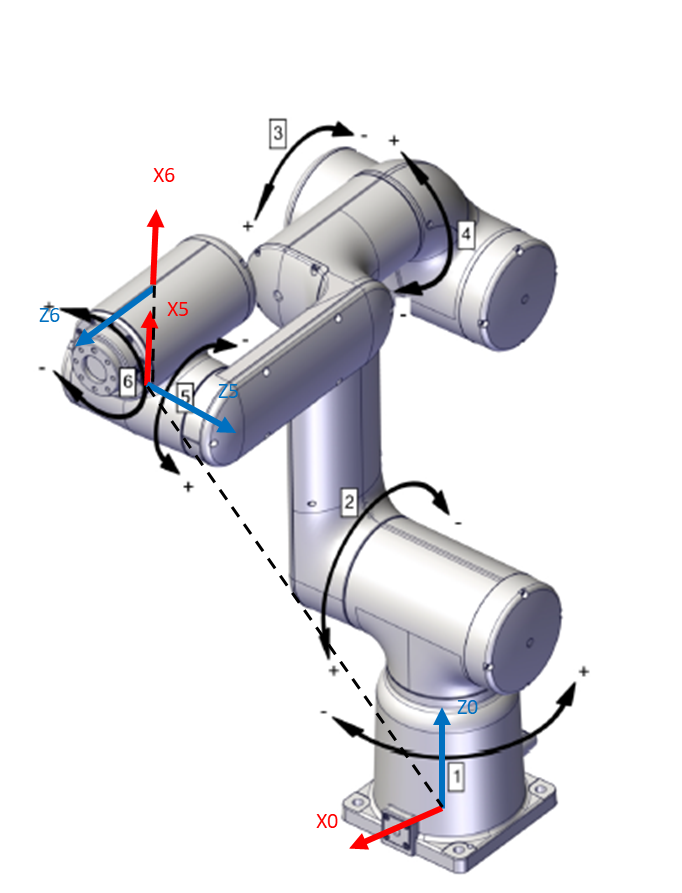


$$^0 P_5 =^0 P_5 -L_6 \cdot^{\;0} {\hat{X} }_6$$



$$^0 P_5 =^0 T_6 -\left\lbrack \begin{array}{c}
-L_6 \\
0\\
0\\
1
\end{array}\right\rbrack$$
